#  CSC 6740 Data Mining: Assignment 1

### NAME: Jesse Annan

### ID: 002708111

### 1. BestBuy Customer Data

% Question 1:
Customer = ["David"; "Lisa"; "Michael"; "Susan"; "William"; "Mat"; "James"; "Kevin"; "Paul"; "Anthony"];
Age = [46; 25; 27; 27; 28; 36; 53; 27; 18; 25];
BestBuy = table(Customer, Age)

BestBuy = 10×2 table
    Customer     Age
    _________    ___

    "David"      46 
    "Lisa"       25 
    "Michael"    27 
    "Susan"      27 
    "William"    28 
    "Mat"        36 
    "James"      53 
    "Kevin"      27 
    "Paul"       18 
    "Anthony"    25 


#### 1.1 mean, median, and mode.

bestbuy_mean = mean(BestBuy.Age)

bestbuy_mean = 31.2000

bestbuy_median = median(BestBuy.Age)

bestbuy_median = 27

bestbuy_mode = mode(BestBuy.Age)

bestbuy_mode = 27

### 2. Climate Data for Atlanta

% Question 2:
Month = ["Jan"; "Feb"; "Mar"; "Apr"; "May"; "Jun"; "Jul"; "Aug"; "Sep"; "Oct"; "Nov"; "Dec"];
Temperature = [52.3; 56.6; 64.6; 72.5; 79.9; 86.4; 89.1; 88.1; 82.2; 72.7; 63.6; 54.0];
AtlClimate = table(Month, Temperature)

AtlClimate = 12×2 table
    Month    Temperature
    _____    ___________

    "Jan"       52.3    
    "Feb"       56.6    
    "Mar"       64.6    
    "Apr"       72.5    
    "May"       79.9    
    "Jun"       86.4    
    "Jul"       89.1    
    "Aug"       88.1    
    "Sep"       82.2    
    "Oct"       72.7    
    "Nov"       63.6    
    "Dec"         54    


#### 2.1 five-number summary

% min, q1, q2 (median), q3, max
min_value = min(AtlClimate.Temperature)

min_value = 52.3000

q1 = quantile(AtlClimate.Temperature, 0.25)

q1 = 60.1000

q2 = median(AtlClimate.Temperature)

q2 = 72.6000

q3 = quantile(AtlClimate.Temperature, 0.75)

q3 = 84.3000

max_value = max(AtlClimate.Temperature)

max_value = 89.1000

#### 2.2 box plot

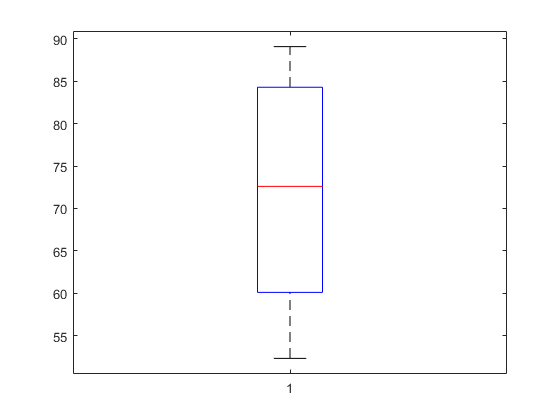

% visualizing Atlanta climate data
boxplot(AtlClimate.Temperature) % no outliers

#### 2.3 plot 

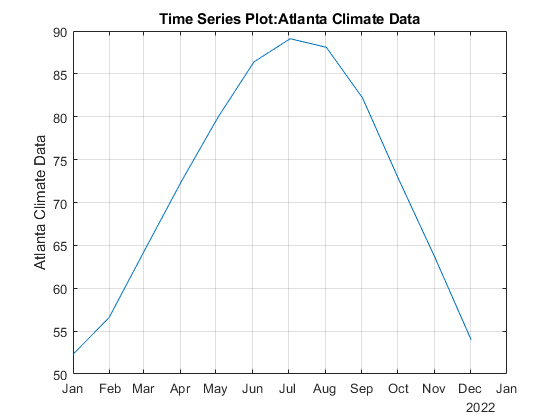

ts = timeseries(AtlClimate.Temperature,1:length(AtlClimate.Temperature));
ts.Name = 'Atlanta Climate Data';
ts.TimeInfo.Units = 'months';
ts.TimeInfo.StartDate = 'Jan';
ts.TimeInfo.Format = 'mmm';
ts.Time = ts.Time - ts.Time(1);
plot(ts)
grid on;

### 3. Customers' Information

% Question 3:
Customer = ["David"; "Susan"; "Lisa"];
Profession = ["Manager"; "Manager"; "Programmer"];
Education = ["B.Sc."; "B.Sc."; "M.Sc."];
Hobbies = ["Golf"; "Swimming"; "Swimming"];
CusInfo = table(Customer,Profession,Education,Hobbies)

CusInfo = 3×4 table
    Customer     Profession     Education     Hobbies  
    ________    ____________    _________    __________

    "David"     "Manager"        "B.Sc."     "Golf"    
    "Susan"     "Manager"        "B.Sc."     "Swimming"
    "Lisa"      "Programmer"     "M.Sc."     "Swimming"


#### 3.1 types of attributes

"nominal attributes"

ans = "nominal attributes"

#### 3.2 similarity between "David" and "Susan"

2/3

ans = 0.6667

#### 3.3 similarity between "Susan" and "Lisa"

1/3

ans = 0.3333

### 4. Patients' Information

Patient = ["Tom"; "Mat"; "Lucy"];
Fever = ["Yes"; "No"; "Yes"];
Cough = ["No"; "Yes"; "Yes"];
Sleepy = ["Yes"; "No"; "No"];
Headache = ["Yes"; "No"; "No"];
RunningNose = ["Yes"; "Yes"; "No"];
Fatigue = ["Yes"; "Yes"; "Yes"];
Sweaty = ["Yes"; "No"; "Yes"];
Dizziness = ["Yes"; "Yes"; "Yes"];
PaInfo = table(Patient,Fever,Cough,Sleepy,Headache,RunningNose,Fatigue,Sweaty,Dizziness)

PaInfo = 3×9 table
    Patient    Fever    Cough    Sleepy    Headache    RunningNose    Fatigue    Sweaty    Dizziness
    _______    _____    _____    ______    ________    ___________    _______    ______    _________

    "Tom"      "Yes"    "No"     "Yes"      "Yes"         "Yes"        "Yes"     "Yes"       "Yes"  
    "Mat"      "No"     "Yes"    "No"       "No"          "Yes"        "Yes"     "No"        "Yes"  
    "Lucy"     "Yes"    "Yes"    "No"       "No"          "No"         "Yes"     "Yes"       "Yes"  


#### 4.1 types of attibutes

"binary attributes"

ans = "binary attributes"

#### 4.2 similarities between "Tom" and "Mat"

4/(4+3+1)

ans = 0.5000

#### 4.3 similarities between "Mat" and "Lucy"

3/(3+2+2)

ans = 0.4286

### 5. Fisher's Iris data

Flower = ["A"; "B"; "C"];
SepalLength = [5.1; 7.0; 4.8];
SepalWidth = [3.5; 3.2; 3.4];
PetalLength = [1.4; 4.7; 1.9];
PetalWidth = [0.2; 1.4; 0.2];
IrisData = table(Flower,SepalLength,SepalWidth,PetalLength,PetalWidth)

IrisData = 3×5 table
    Flower    SepalLength    SepalWidth    PetalLength    PetalWidth
    ______    ___________    __________    ___________    __________

     "A"          5.1           3.5            1.4           0.2    
     "B"            7           3.2            4.7           1.4    
     "C"          4.8           3.4            1.9           0.2    


#### 5.1 types of attributes

"numeric attributes"

ans = "numeric attributes"

#### 5.2 similarity measure used

"Pearson's correlation coefficient"

ans = "Pearson's correlation coefficient"

#### 5.3 similarity between "A" and "B"

A = table2array(IrisData(1,2:end));
B = table2array(IrisData(2,2:end));
AB_Similarity = corrcoef(A,B)

AB_Similarity =     1.0000    0.7866
    0.7866    1.0000


#### 5.4 similarity between "B" and "C"

C = table2array(IrisData(3,2:end));
BC_Similarity = corrcoef(B,C)

BC_Similarity =     1.0000    0.8331
    0.8331    1.0000


### 6. Loan company customers' information

Customer = ["Kevin"; "John"; "Daniel"];
CreditScoreRange = ["Excellent"; "Very good"; "Good"];
SalaryRange = ["High"; "Very High"; "Medium"];
Age = ["Senior"; "Middle Age"; "Young"];
custInfo = table(Customer,CreditScoreRange,SalaryRange,Age)

custInfo = 3×4 table
    Customer    CreditScoreRange    SalaryRange        Age     
    ________    ________________    ___________    ____________

    "Kevin"       "Excellent"       "High"         "Senior"    
    "John"        "Very good"       "Very High"    "Middle Age"
    "Daniel"      "Good"            "Medium"       "Young"     


#### 6.1 types of attributes

"ordinal attributes"

ans = "ordinal attributes"

#### 6.2 similarity between "Kevin" and "John"

#### 6.3 similarity between "John" and "Daniel"

#### 7. min-max normalization

Patient = ["Tom"; "Mat"; "Lucy"; "Brain"];
Height = [5.7; 6.2; 5.1; 6.4];
mytable = table(Patient, Height)

mytable = 4×2 table
    Patient    Height
    _______    ______

    "Tom"       5.7  
    "Mat"       6.2  
    "Lucy"      5.1  
    "Brain"     6.4  


nHeight = normalize(mytable.Height,"range");
mytable2 = table(Patient,nHeight)

mytable2 = 4×2 table
    Patient    nHeight
    _______    _______

    "Tom"      0.46154
    "Mat"      0.84615
    "Lucy"           0
    "Brain"          1
